HW3

Question 1

a = pi/2;                                % interval half-length
f = @(x) sin(x) - 0.5;

%% ---------- (a) Taylor series around x=0, built by hand (not using taylor()) ----------
% sin x = x - x^3/3! + x^5/5! - x^7/7! + ...
% So: f(x) = -0.5 + x - x^3/6 + x^5/120 - x^7/5040 + ...
% We'll display the first few terms explicitly.
fprintf('(a) Taylor around 0 (first 7 terms shown):\n');

(a) Taylor around 0 (first 7 terms shown):


% coefficients for [-0.5, 1*x, 0*x^2, -1/6*x^3, 0*x^4, 1/120*x^5, 0*x^6, -1/5040*x^7]
fprintf('f(x) ≈ -1/2 + x - (1/6)x^3 + (1/120)x^5 - (1/5040)x^7 + ...\n\n');

f(x) ≈ -1/2 + x - (1/6)x^3 + (1/120)x^5 - (1/5040)x^7 + ...



b)

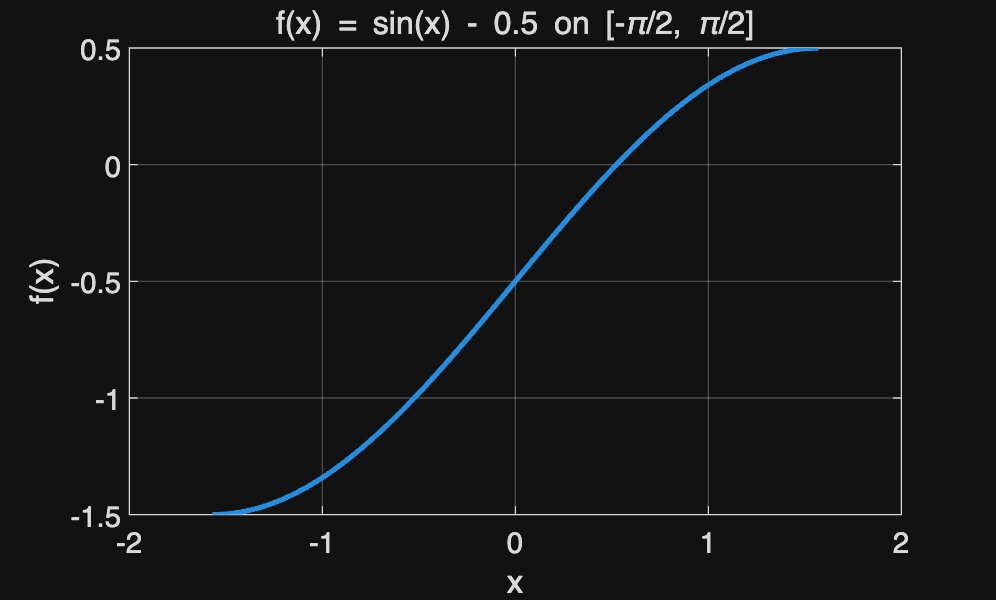

xx = linspace(-a, a, 1000);
figure; plot(xx, f(xx), 'LineWidth', 2);
xlabel('x'); ylabel('f(x)'); title('f(x) = sin(x) - 0.5 on [-\pi/2, \pi/2]'); grid on;


%% Helper: exact integrals we'll need (closed-form, no numeric quadrature)
I1   = @(L) 2*L;                         % ∫_{-L}^L 1 dx
Ix   = @(L) 0;                           % ∫_{-L}^L x dx (odd)
Ix2  = @(L) 2*L^3/3;                     % ∫_{-L}^L x^2 dx
Ix3  = @(L) 0;                           % ∫_{-L}^L x^3 dx (odd)
Ix4  = @(L) 2*L^5/5;                     % ∫_{-L}^L x^4 dx
Isin = @(L) 0;                           % ∫_{-L}^L sin x dx (odd)
% ∫_{-L}^L x sin x dx = [-x cos x + sin x]_{-L}^L = -2L cos L + 2 sin L
Ixsin = @(L) -2*L*cos(L) + 2*sin(L);
% ∫_{-L}^L x^2 sin x dx is odd (x^2 even * sin odd) => 0
Ix2sin = @(L) 0;